**May 27 2023**

# **Predicting ****Conflict**** Errors: Integrating Convolutional Neural Networks and Whole-Brain Modeling of Preparatory Electrophysiological Activity**

**Neda Kaboodvand1,2, Hannieh Karimi3, Behzad Iravani1,4**

1 Department of Clinical Neuroscience, Karolinska Institutet, Stockholm, Sweden.

2 Department of Neurosurgery, University of Pennsylvania, Philadelphia, USA 

3 Medicine of Tehran University of Medical Sciences, Tehran university, Tehran, Iran.  

4 Department of Neurology and Neurological Sciences, Stanford University, Stanford, USA.

Cognitive control refers to humans' ability to regulate, coordinate, and sequence their thoughts and activities in accordance with their behavioral goals. Despite extensive research in the last two decades, the underlying mechanisms of cognitive control in humans are still not fully understood. The neural activity is often difficult to interpret, and the precise mechanisms by which they contribute to cognitive control remained unclear. This could imply that the commonly used analysis methods that are agnostic to theoretical neural-mass dynamics are incapable of fully elucidating the complex dynamics of cognitive control. In this study, a convolutional neural network is utilized to interpret both empirical and theoretical data as part of a multi-modal computational framework that we are building. According to our findings, the insula and angular cortices have the highest predictive value for conflict-error. Yet the whole-brain model only supported the stimulation of the angular gyrus for enhancing cognitive control.

restoredefaultpath % reset matlab path
addpath('C:\MatlabToolboxes\fieldtrip-master\fieldtrip-master')
ft_defaults()

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

addpath(genpath(pwd))

## **Behavioral Data**

**Database1:**

BHV = report_behvaior_dataset1();

total number of individuals: 35 
number of Hit : 204.17 +/- 15.01 
mean rt of Hit : 726.45 +/- 54.70 
number of Error : 21.11 +/- 13.32 
mean rt of Error : 715.15 +/- 95.15 


## Localizeing time and spcae using CNN

The data from the python scripts are stored in matlab object for further postprocessing and visualizetion 

% clear memory and load the data object
clc
clear all
disp('loading CNN data')

loading CNN data


load data\interp\matlab\CNNData.mat
disp('done!')

done!


**Step 1)** displaying the accuracy for traning, cross validation  and testing 

Data.whats_acc

training : 66.7
cross-val : 64.2
testing : 64.3


**Step 2)** learning rate 

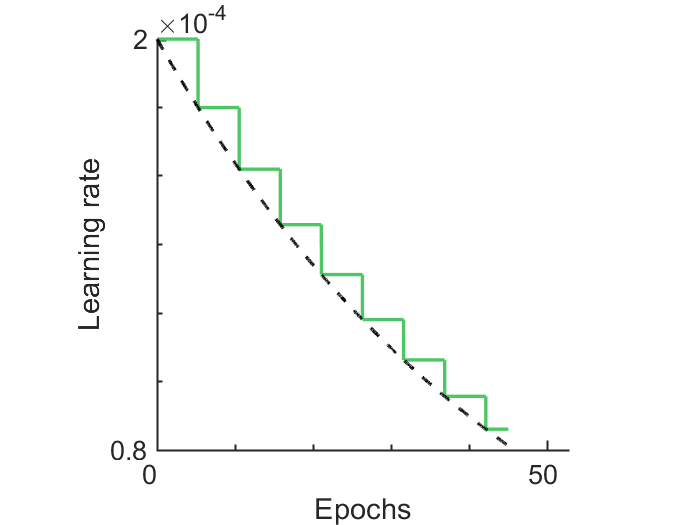

Data.plot_learning_rate(45, 2e-4, .90, 1000, 16)

**Step 3)** plotting the learning curve to show the training and cross validation the accuracy and the performance loss function 

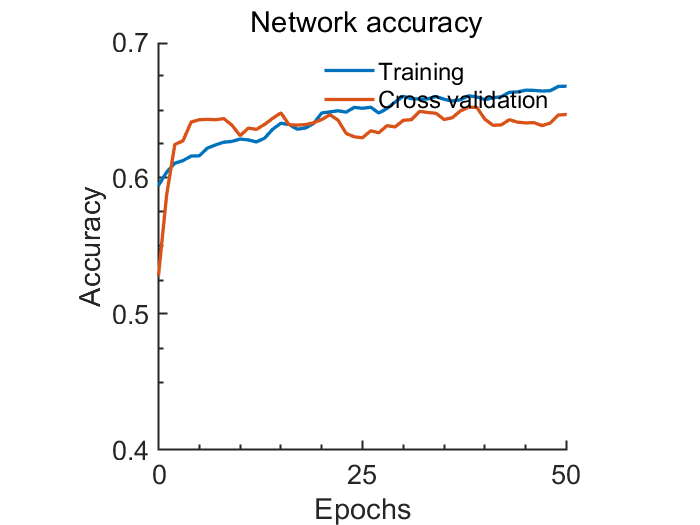

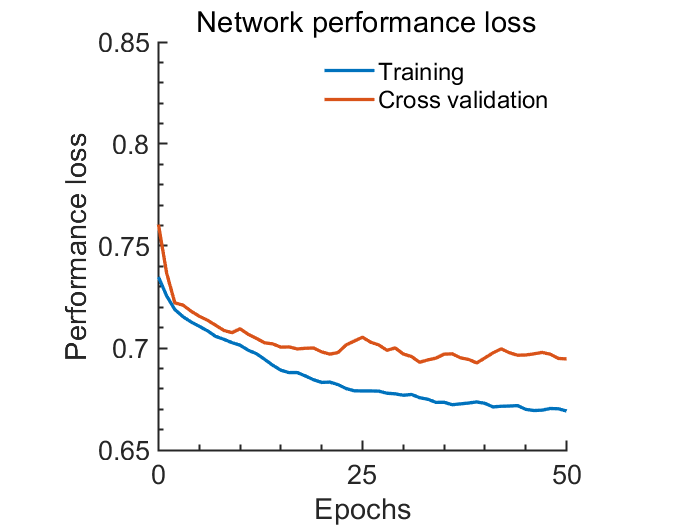

Data.plot_learning_loss

**Step 4)** dispalying mean activation error per channel for class **conflict error**

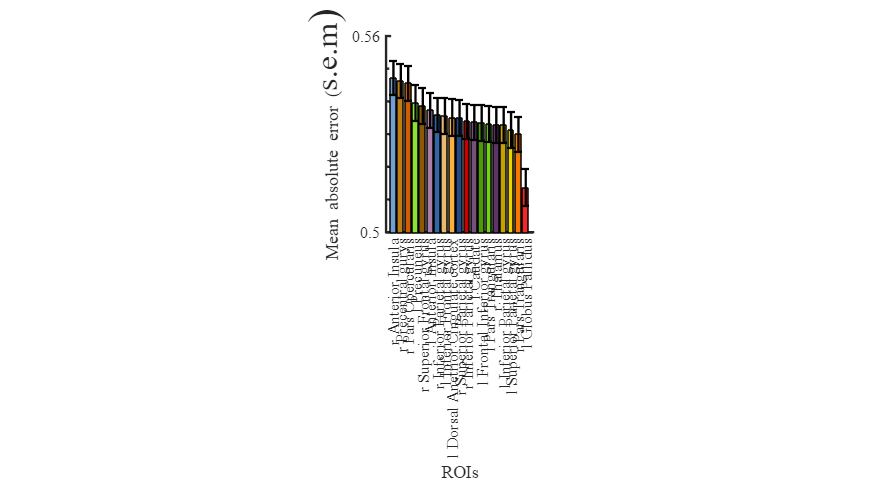

[m,s, ix] = Data.plot_MAE_chan([.50,.56],[.75 1 1], 1);

m = flipud(m); % decending 
s = flipud(s); % decending 
save('OrderMAE.mat', 'ix');

**Step 5) **find the explanability knee

window_size = 3;
knee= find_knee(m, window_size)

knee = 3

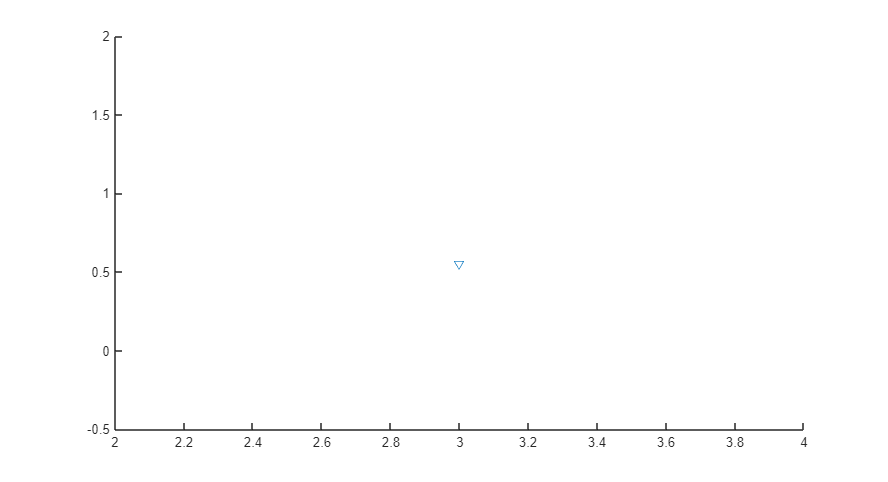

scatter(knee, m(knee)*1.01, 'v')

% permtation test 
% for reproducibility 
rng(1)
nrep = 5e3;
iperm = randi(length(Data.MeanAverageError_chan.MAE_AVG(:,1)), 1,nrep);

t = ((1-Data.MeanAverageError_chan.MAE_AVG(:,1)) -...
        nanmean(1-Data.MeanAverageError_chan.MAE_AVG(iperm,1)))...
        ./ (std(1-Data.MeanAverageError_chan.MAE_AVG(iperm,1)));


fprintf('t = %1.2f \n', t(fliplr(ix(end-2:end)')))

t = 1.73 
t = 1.57 
t = 1.48 


format long
ci = 0;
for i = fliplr(ix(end-2:end)')
    Data.nodeLabel(i,:)
    ci = ci+1;
    p(ci) = mean(Data.MeanAverageError_chan.MAE_AVG(i,1)>=Data.MeanAverageError_chan.MAE_AVG(iperm,1));
    p(ci)
    1-Data.MeanAverageError_chan.MAE_AVG(i,1)
end

ans = 1×6 table
         RegionLabel         Extent        t_value         x     y     z
    _____________________    ______    ________________    __    __    _

    {'r Anterior Insula'}     2022     6.25519990921021    38    18    2


ans =    0.049200000000000


ans = single
   0.5473534


ans = 1×6 table
         RegionLabel          Extent        t_value         x      y     z 
    ______________________    ______    ________________    __    ___    __

    {'r Precentral gurys'}     663      5.16225576400757    38    -14    62


ans =    0.099400000000000


ans = single
   0.5462679


ans = 1×6 table
         RegionLabel          Extent        t_value         x     y    z 
    ______________________    ______    ________________    __    _    __

    {'r Pars Opercularis'}     2022     6.86828422546387    46    8    28


ans =    0.151600000000000


ans = single
   0.5456350


fprintf('p = %1.3f', round(p,3))

p = 0.049p = 0.099p = 0.152

**Step 5) **gradCAM 

% clf
% s2r = Data.plot_grad_cam(Data, ...
%     'C:\Users\behira\OneDrive - Karolinska Institutet\Desktop\Manuscript\CognitiveControl\scripts\data\interp\matlab',...
%     'C:\Users\behira\OneDrive - Karolinska Institutet\Desktop\Manuscript\CognitiveControl\scripts\figures\DS01', true);

**Step 6)** displaying the learned filter for each ROI 

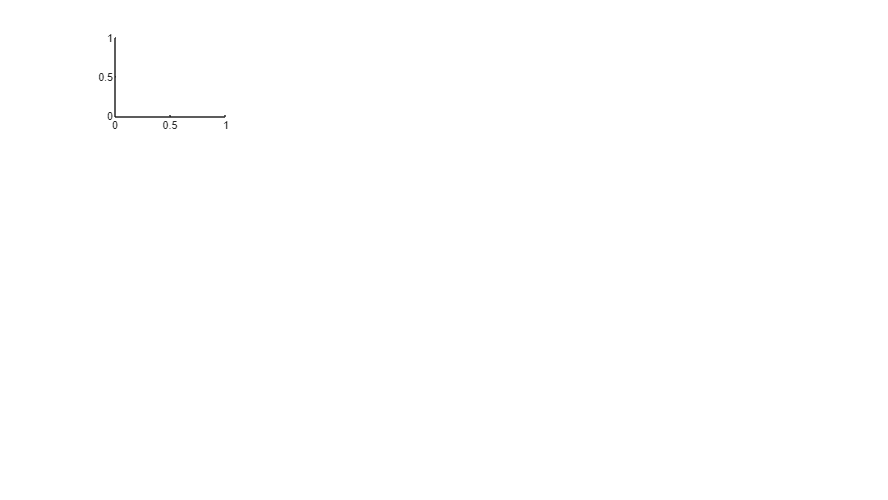

Error using interp1>reshapeAndSortXandV
X and V must be of the same length.

Error in interp1 (line 128)
    [X,V,orig_size_v] = reshapeAndSortXandV(X,V);

Error in CNNdata/plot_learned_filters (

 peaks_f = Data.plot_learned_filters(14, fliplr(ix));

## Time course test sample source filtered by CNN

[b, p, CI, stat]=Data.apply_filter([9,8]);
close all
col = Data.getColor();
pl(1) = plot(Data.data_incong_hit_err.data.time(1:length(stat{1, 1}.tstat)),  stat{1, 1}.tstat, 'LineWidth',1.6, 'Color', col(9,:))
hold on
pl(2) = plot(Data.data_incong_hit_err.data.time(1:length(stat{1, 2}.tstat)), stat{1, 2}.tstat, 'LineWidth',1.6,'Color', col(8,:))
xlim([-.8,-.6])
box off
xticks(-.8:.1:-.6); yticks(-2.5:2.5:2.5)
set(gca, 'FontName', 'Arial Nova Cond', 'FontSize', 16, 'LineWidth', 2)
ylim([-2.5, 2.5])
yline(tinv(.025, stat{1, 1}.df(1)), 'LineStyle', '--'), yline(tinv(.975, stat{1, 1}.df(1)), 'LineStyle', '--')
xlabel('Time(s)')
ylabel('T-value')
title('Hit > Error')
legend(pl, Data.nodeLabel{[9,8],"RegionLabel"}, 'Box', 'off')

The simulated time courses using neural mass model for each stimulation setting Is tested with the trained CNN 

close all
path = {'data\source\python_simulation\C\'; 'data\source\python_simulation'};
%% Construct result_stimulation object 
sine_stimulation_results = results_stimulation(path);  
%% Plot the search parameter 
sine_stimulation_results.plot_parameters();
print -dsvg figures\DS01\DS01_fitC.svg

xlim([0.0025 0.0273])
ylim([0.045 0.543])
ax = gca;
chart = ax.Children(2);
datatip(chart,0.02066,0.5321);

sine_stimulation_results.report_stat(5e3);

%% Plot TCs after in silico stimulation 
figure
sine_stimulation_results.plot_stimulatation_inslico_TCs()

figure('Units','normalized',Position=[0 0 1 1])
sine_stimulation_results.stimulating_three_first_rois(["ROI 12-6"])
pbaspect([.33,1,1])
print -dsvg -vector figures\DS01\DS01_stimulation_heatmap.svg

ROIS = [ "ROI 9-1","ROI 8-2", "ROI 16-3", "ROI 3-4", "ROI 17-5" "ROI 12-6"...
    "ROI 10-7", "ROI 6-8", "ROI 11-9", "ROI 15-10", "ROI 19-11", "ROI 2-12", "ROI 14-13", "ROI 4-14", "ROI 13-15",...
    "ROI 1-16", "ROI 7-17", "ROI 5-18", "ROI 18-19"];
figure('Units','normalized',Position=[0 0 1 1])
sine_stimulation_results.stimulating_three_first_rois(ROIS)
print -dsvg -vector figures\DS01\DS01_supp_stimulation_heatmap.svg


[t, p , cirange] = sine_stimulation_results.stimulating_rois_stat(ROIS);
a = linspace(.33,5, 20);
f = linspace(2,200, 20);
[tmax, imx] = max(t,[],'all');
[ind.f,ind.a, ind.roi] = ind2sub(size(t), imx);
fprintf("ROI (%s): t(18) = %1.2f, p = %1.4f @ a= %1.2f f= %1.2f\n", ROIS(ind.roi), t(imx), 2*(1-tcdf(t(imx),18)), a(ind.a), f(ind.f))


clf
ax = sine_stimulation_results.implot(t(:,:,ind.roi),[2,4.5]);
pbaspect([.33,1,1])
cb = colorbar();
ylabel(cb, 'T-value')
axis xy
ax.XAxis.Color = 'w'
ax.YAxis.Color = 'w'
print -dsvg -vector figures\DS01\DS01_stimulation_heatmap_stats.svg



figure
s =sine_stimulation_results.stimulating_traceplot(["ROI 9-1", "ROI 8-2", "ROI 16-3", "ROI 3-4", "ROI 17-5" "ROI 12-6"...
    "ROI 10-7", "ROI 6-8", "ROI 11-9", "ROI 15-10", "ROI 19-11", "ROI 2-12", "ROI 14-13", "ROI 4-14", "ROI 13-15",...
    "ROI 1-16", "ROI 7-17", "ROI 5-18", "ROI 18-19"])
print -dsvg -vector figures\DS01\DS01_stimulation_bar.svg